This is some of the spray data taken from the table and converted to inches

dwl=[13 48 66 75 80 82 80 77 72 63 44]

dwl =     13    48    66    75    80    82    80    77    72    63    44


station2=[61;57;55;52;48;41;32;20;9;0]

station2 =     61
    57
    55
    52
    48
    41
    32
    20
     9
     0


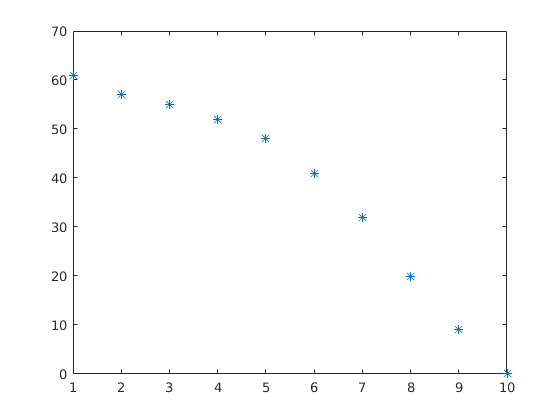

x = linspace(1, size(station2, 1), size(station2, 1))';
plot(x, station2, '*')

A = [x.^2 x ones(size(x))];
p = A\station2;

x_exp = linspace(1, 10, 100)';
A_exp = [x_exp.^2 x_exp ones(size(x_exp))]

A_exp =     1.0000    1.0000    1.0000
    1.1901    1.0909    1.0000
    1.3967    1.1818    1.0000
    1.6198    1.2727    1.0000
    1.8595    1.3636    1.0000
    2.1157    1.4545    1.0000
    2.3884    1.5455    1.0000
    2.6777    1.6364    1.0000
    2.9835    1.7273    1.0000
    3.3058    1.8182    1.0000


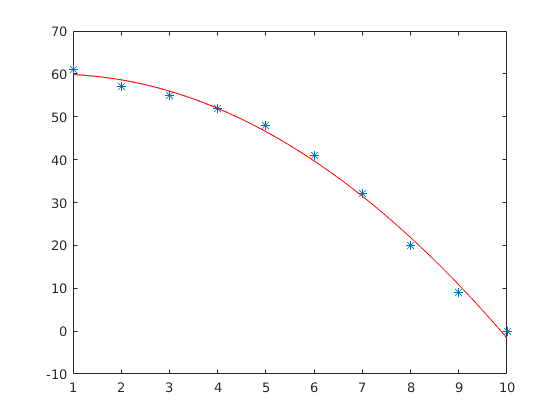

y_exp = A_exp * p;
plot(x, station2, '*', x_exp, y_exp, 'r')

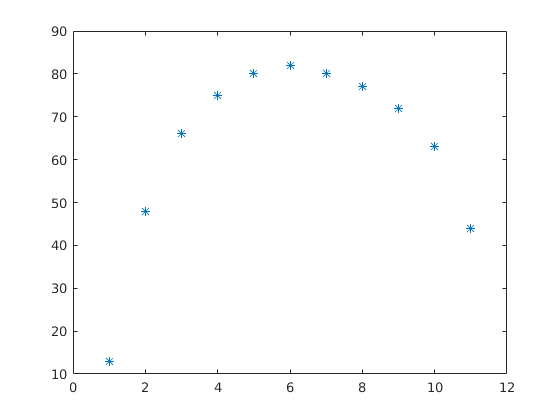

x_dwl = linspace(1, size(dwl, 2), size(dwl, 2))';
plot(x_dwl, dwl, '*')

A_dwl = [x_dwl.^2, x_dwl, ones(size(x_dwl))];
p_dwl = A_dwl\dwl';
x_exp_dwl = linspace(1, 11, 100)';
A_exp_dwl = [x_exp_dwl.^2 x_exp_dwl ones(size(x_exp_dwl))];

A_exp_dwl =     1.0000    1.0000    1.0000
    1.2122    1.1010    1.0000
    1.4449    1.2020    1.0000
    1.6979    1.3030    1.0000
    1.9713    1.4040    1.0000
    2.2652    1.5051    1.0000
    2.5794    1.6061    1.0000
    2.9141    1.7071    1.0000
    3.2692    1.8081    1.0000
    3.6446    1.9091    1.0000


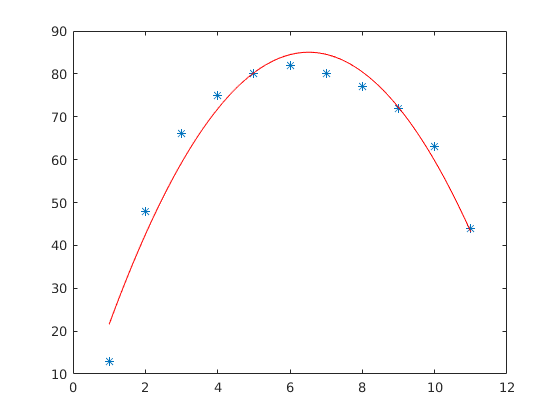

y_exp_dwl = A_exp_dwl * p_dwl;
plot(x_dwl, dwl, '*', x_exp_dwl, y_exp_dwl, 'r')

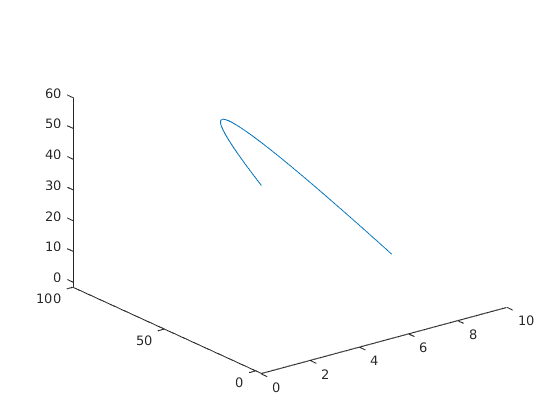

x3 = linspace(0, 10, 100)';
A3 = [x3.^2 x3 ones(size(x3))];
s3 = A3*p;
d3 = A3*p_dwl;
plot3(x3, d3, s3)